images\seashell_five.jpg


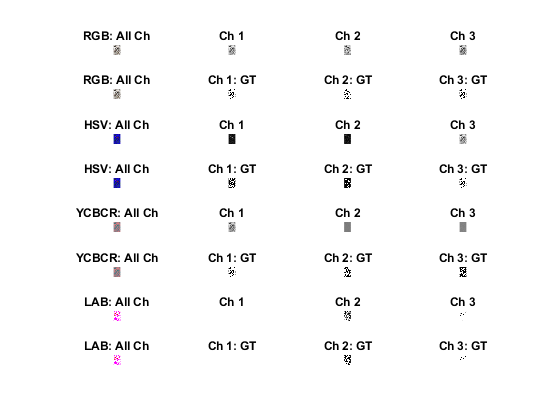

images\shellfish_four.jpg


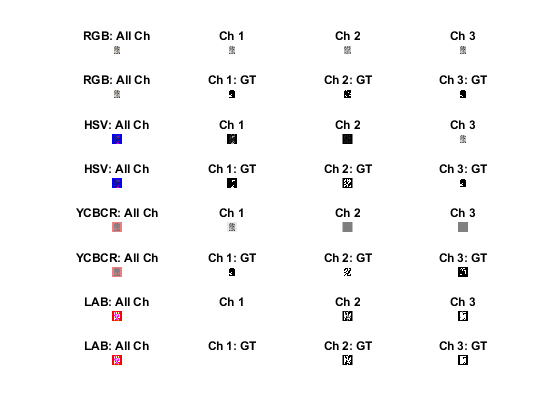

images\starfish.jpg


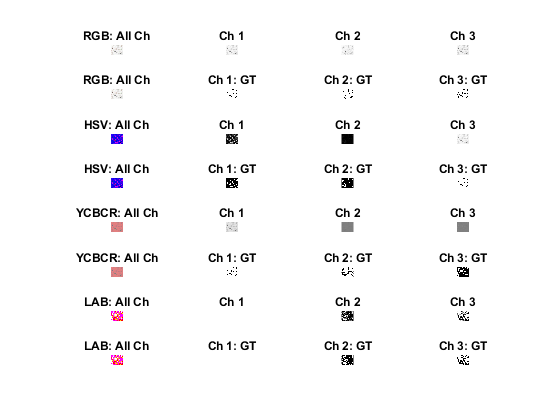

images\starfish_17.jpg


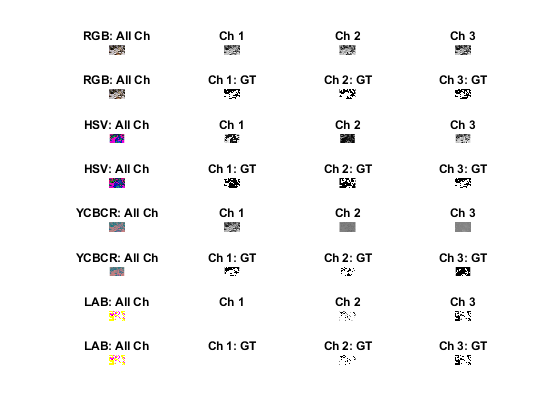

images\starfish_5.jpg


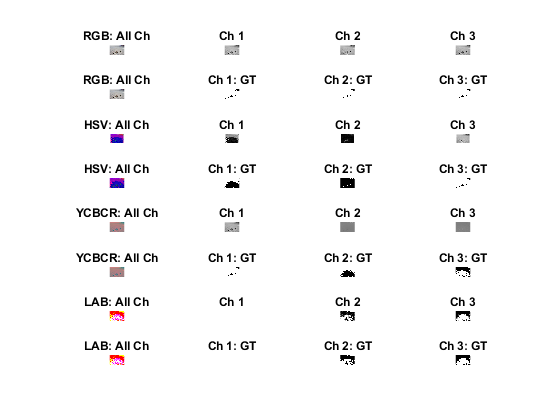

images\starfish_map0.jpg


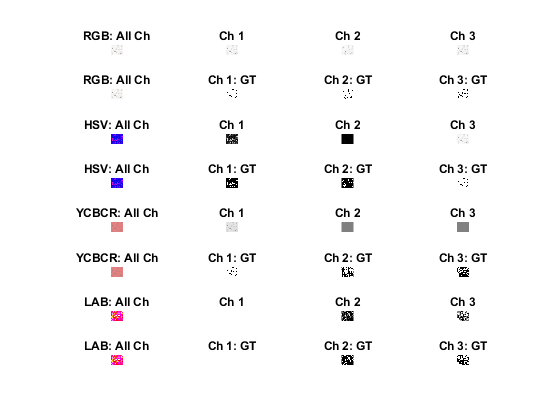

images\starfish_map1.jpg


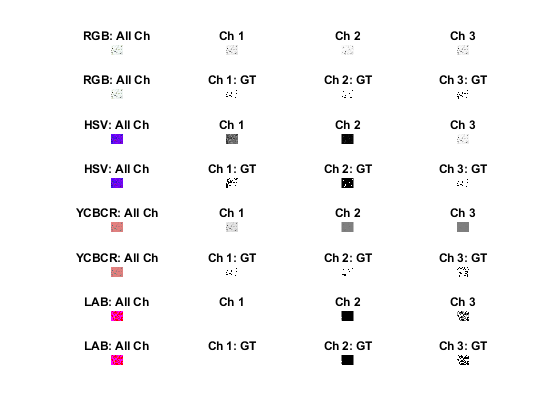

images\starfish_map2.jpg


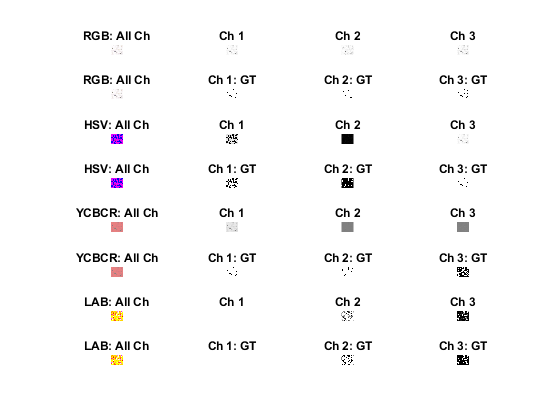

images\starfish_map3.jpg


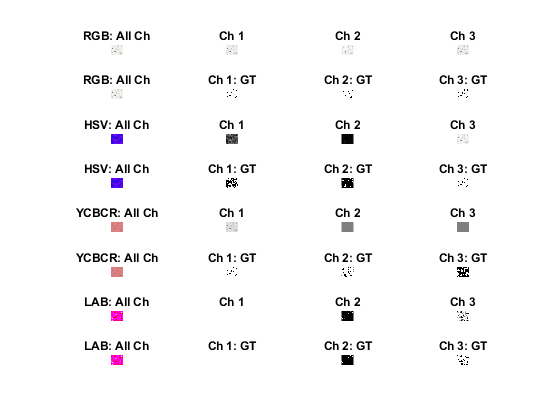

images\starfish_noise1.jpg


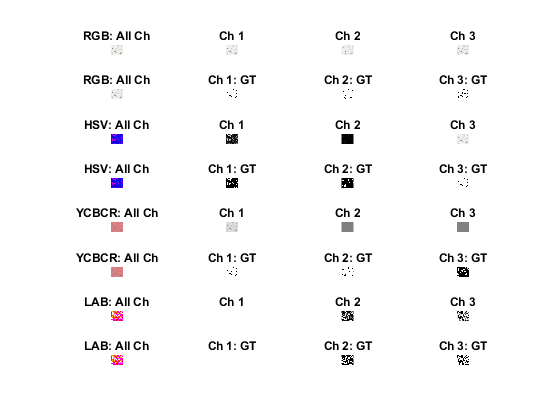

images\starfish_noise10.jpg


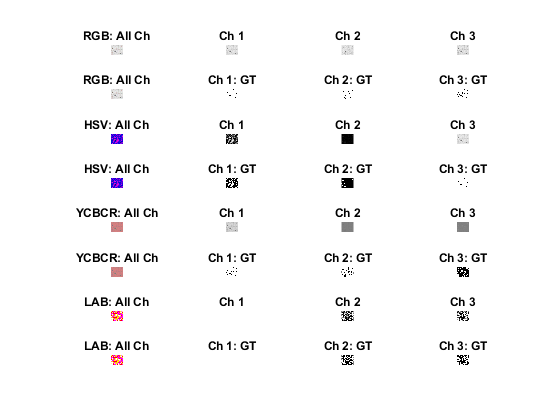

images\starfish_noise2.jpg


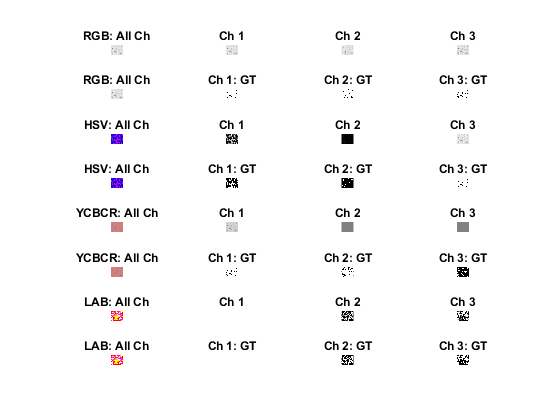

images\starfish_noise3.jpg


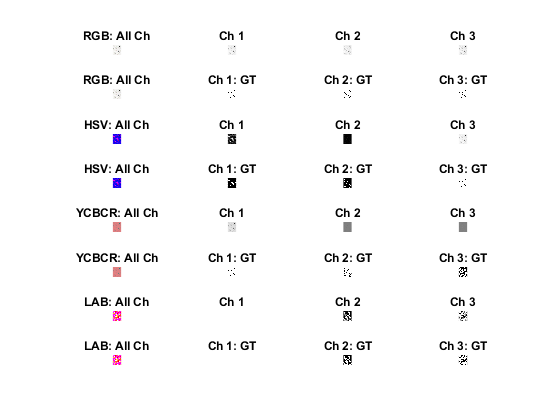

images\starfish_noise4.jpg


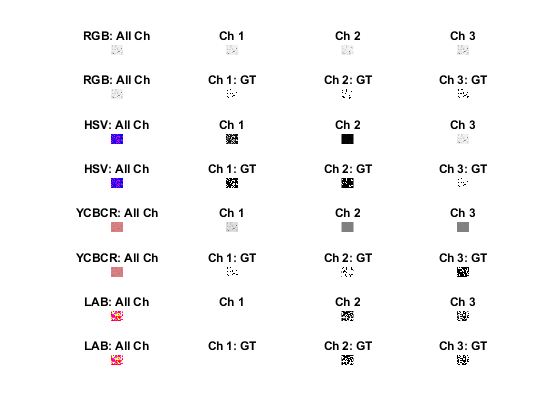

images\starfish_noise5.jpg


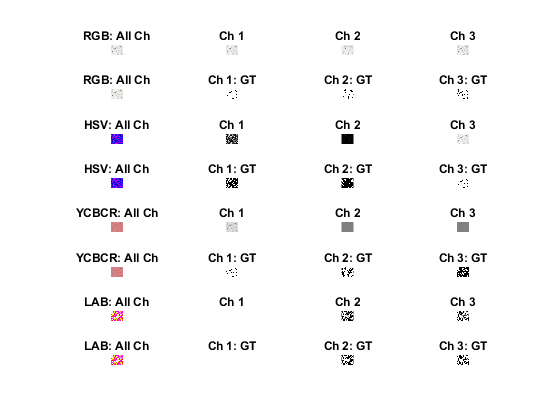

images\starfish_noise6.jpg


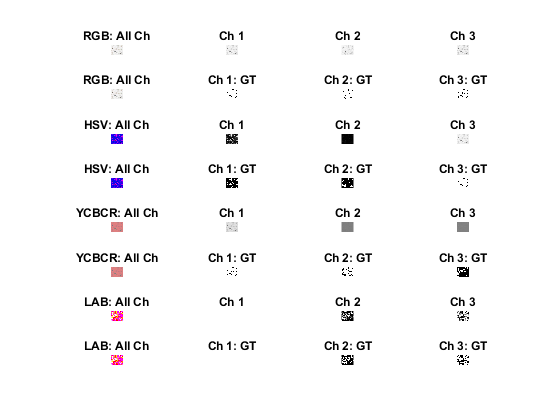

images\starfish_noise7.jpg


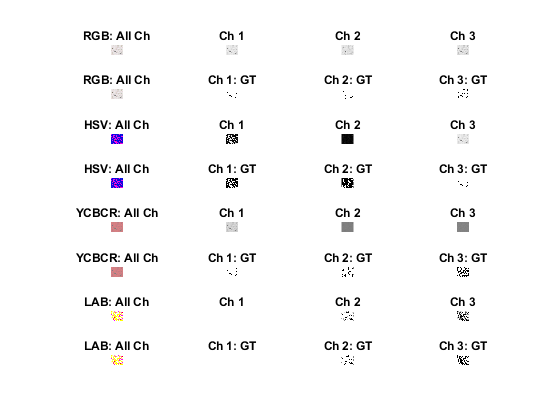

images\starfish_noise8.jpg


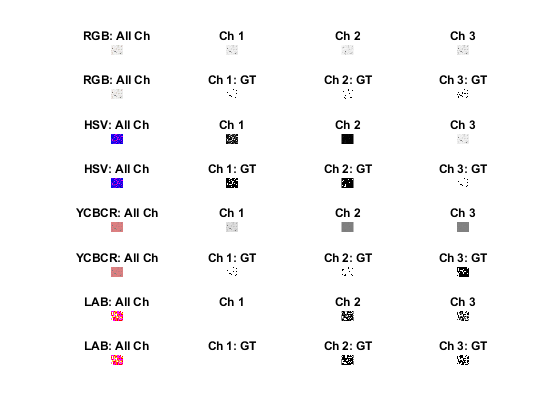

images\starfish_noise9.jpg


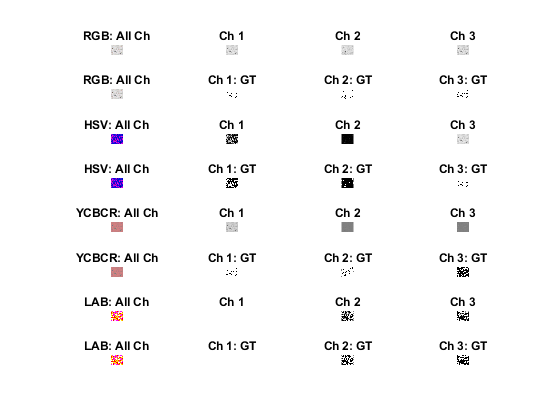

images\starfish_overlaid.jpg


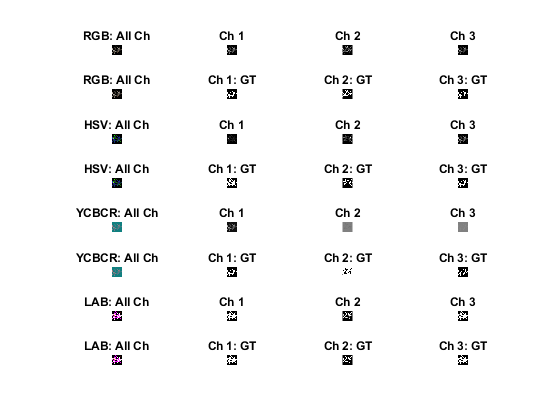

files = GetFilesInSubDir("images");

for i = 1:numel(files)
    filepath = files(i);
    
    disp(filepath)
    
    im = imread(filepath);
%     im = rgb2gray(im);
    
%     DENOISE
    im = medfilt3(im, [5 5 5]);
    
    figure
    r = 8;
    c = 4;
    n = 1;
    for j = 1:4
        
        if j == 1
            colModel = "RGB";
            imAlt = im;
        elseif j == 2
            colModel = "HSV";
            imAlt = rgb2hsv(im);
        elseif j == 3
            colModel = "YCBCR";
            imAlt = rgb2ycbcr(im);
        elseif j == 4
            colModel = "LAB";
            imAlt = rgb2lab(im);
        end
        
        % Separate and denoise channels
        [ch1,ch2,ch3] = imsplit(imAlt);
        
        subplot(r,c,n);
        imshow(imAlt)
        title(colModel + ": All Ch");
        n = n + 1;
        
        subplot(r,c,n);
        imshow(ch1)
        title("Ch 1");
        n = n + 1;
        
        subplot(r,c,n);
        imshow(ch2)
        title("Ch 2");
        n = n + 1;
        
        subplot(r,c,n);
        imshow(ch3)
        title("Ch 3");
        n = n + 1;
        
%         Grey thresholds.
        subplot(r,c,n);
        imshow(imAlt)
        title(colModel + ": All Ch");
        n = n + 1;
        
        level = graythresh(ch1);
        ch1gt = imbinarize(ch1,level);
        subplot(r,c,n);
        imshow(ch1gt)
        title("Ch 1: GT");
        n = n + 1;
        
        level = graythresh(ch2);
        ch2gt = imbinarize(ch2,level);
        subplot(r,c,n);
        imshow(ch2gt)
        title("Ch 2: GT");
        n = n + 1;
        
        level = graythresh(ch3);
        ch3gt = imbinarize(ch3,level);
        subplot(r,c,n);
        imshow(ch3gt)
        title("Ch 3: GT");
        n = n + 1;
        
    end
    
end


function filepaths = GetFilesInSubDir(subDir)
    files = dir(subDir);
    files = files(~ismember({files.name}, {'.', '..'})); % Remove navigation elements from struct.
    filepaths = subDir + "\" + {files.name};
end